**Funkcja kary zewnętrzna**

f = @(x) 0.2*x+0.4*sin(10*x)+(0.1*x^2-0.4)^2;
g_1 = @(x) -x+0.2;
g_2 = @(x) x-4;
g = {g_1, g_2};

x_min = kara_zewnetrzna(f, g, -4, 0.5, 0.001)

x_min = 0.4680

f_min = f(x_min)

f_min = -0.1632


figure
fplot(f)

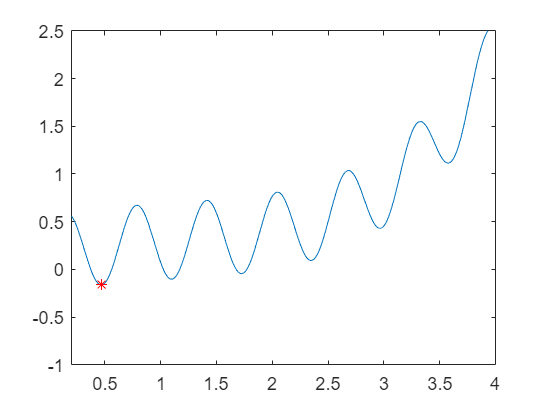

hold on;
plot(x_min, f_min, 'r*')
xlim([0.2, 4])
ylim([-1, 2.5])
hold off;

**Funkcja kary wewnętrzna**

f = @(x) 0.2*x+0.4*sin(10*x)+(0.1*x^2-0.4)^2;
g_1 = @(x) -x-1.7;
g_2 = @(x) x^5;
g = {g_1, g_2};

x_min = kara_wewnetrzna(f, g, -0.6, 4, 0.001, 0.5, 1)

x_min = -1.4203

f_min = f(x_min)

f_min = -0.6439


figure
fplot(f)

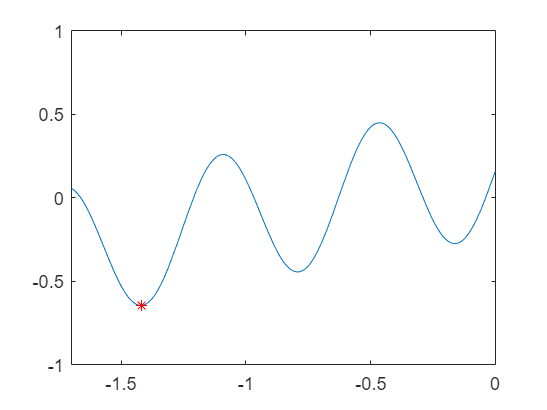

hold on;
plot(x_min, f_min, 'r*')
xlim([-1.7, 0])
ylim([-1, 1])
hold off;

function x_min = kara_wewnetrzna(f, g, x0, c, eps, alpha, h)
    % f - funkcja w której minimum chcemy znaleźć
    % g - ograniczenia
    % x0 - punkt poczatkowy
    % c - współczynnik kary
    % eps - dokładność obliczeń
    % alpha - współczynnik skalowania kary
    % h - flaga (wybór jednej z dwóch funkcji kary)
    if c <= 0 || eps <= 0 || alpha <= 0 || alpha >= 1
        error("Niepoprawne parametry")
    end
    for j = 1:length(g)
        if g{j}(x0) > 0
            error("Punkt startowy poza zbiorem dopuszczalnym")
        end
    end     % zakończenie sprawdzania warunków 
    x(:, 1) = x0';
    options = optimset('MaxIter', 10, 'Display', 'off');
    S = @(z) 0;     % inicjalizacja funkcji S
    if h == 1
        for j = 1 : length(g)
            S = @(z) S(z)-log(-g{j}(z));
        end
    else
        for j = 1 : length(g)
            S = @(z) S(z)-1/(g{j}(z));
        end
    end 
    F = @(z) f(z) + c * S(z);   % inicjalizacja funkcji F
    x(:, 2) = fminsearch(F, x(:, 1)', options)';
    c = alpha * c;
    i = 2;
    while sqrt(sum((x(:, i)'-x(:, i-1)').^2)) > eps 
        % warunek dokładności 
        i = i + 1;
        S = @(z) 0;
        if h == 1
            for j = 1 : length(g)
                S = @(z) S(z)-log(-g{j}(z));
            end
        else
            for j = 1 : length(g)
                S = @(z) S(z)-1/(g{j}(z));
            end
        end
        F = @(z) f(z) + c * S(z);
        x(:, i) = fminsearch(F, x(:, i-1)', options)';
        c = alpha * c;
    end
    x_min = x(:, i);
end


function x_min = kara_zewnetrzna(f, g, x0, c, eps)
    % f - funkcja w której minimum chcemy znaleźć
    % g - ograniczenia
    % x0 - punkt poczatkowy
    % c - współczynnik kary
    % eps - dokładność obliczeń
    if c <= 0 || eps <= 0
        error("Niepoprawne parametry")
    end
    
    x(:, 1) = x0';
    S = @(z) 0;     % inicjalizacja funkcji S
    for j = 1 : length(g)
        S = @(z) S(z) + max(0, g{j}(z))^2;
    end
    
    F = @(z) f(z) + c*S(z);
    x(:, 2) = fminsearch(F, x(:, 1)')';
    c = 2*c;
    i = 2;
    while sqrt(sum((x(:, i)'-x(:, i-1)').^2)) > eps
        % warunek dokładności
        i = i+1;
        S = @(z) 0;
        for j = 1:length(g)
            S = @(z) S(z) + max(0, g{j}(z))^2;
        end 
        F = @(z) f(z) + c * S(z);
        x(:, i) = fminsearch(F, x(:, i-1)')';
        c = 2*c;
    end 
    x_min = x(:, i);
end
